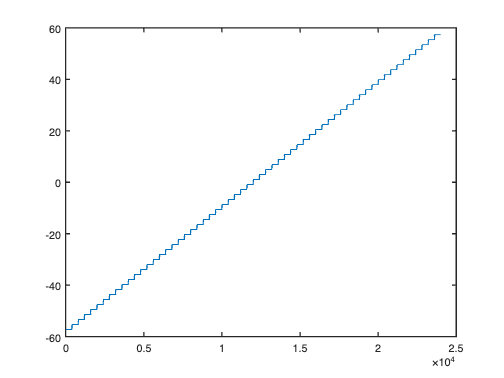

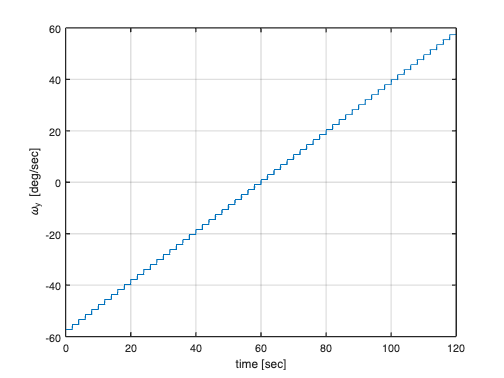

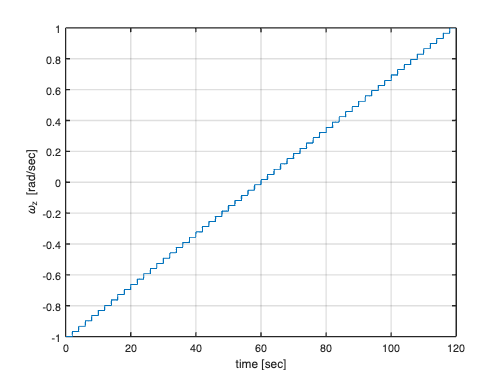

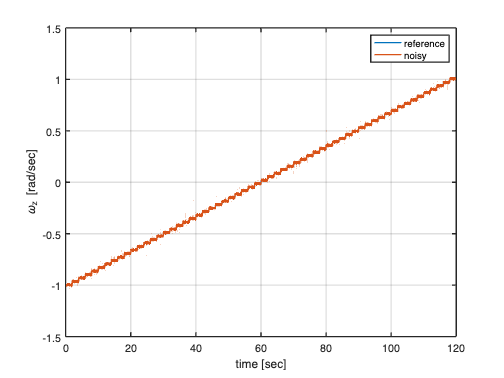

clear all;
close all;
clc;

set(0,'defaultaxeslinewidth',1.5);
set(0,'defaultlinelinewidth',1.5);
set(0,'DefaultAxesFontSize', 12);

% IMU parameters
ref_grav    = 9.81;                 % reference gravity  in [m/s2]
ref_omeg    = 1;                    % MEMS reference rotation in [rad/s]

%% call simulation function to 'simulate' and collect the data
f_imu           = 200;            % IMU sample rate in [Hz]
simulation      = adapted_STEP_GYRORATES(f_imu, ref_omeg);

%% collected data from simulation
%% gyroscope values
g_xup               = simulation.g_xup;
gyr_ref             = simulation.gyro_reference;

% %% Deterministic and Stochastic errors
bias_gyro           = simulation.bias_gyro;
SF_gyro             = simulation.SF_gyro;
ARW                 = simulation.ARW;

% % Split the data into training and testing sets
split_ratio             = 0.6; % 60% training, 20% validation, 20% testing
num_samples             = size(g_xup, 1);
split_idx_train         = round(split_ratio * num_samples);
split_idx_val           = round(0.8 * num_samples);


% % split the data to training, validation and testing, including the reference data
% Training sets
train_data_gyr      = num2cell(g_xup(1:split_idx_train, :),1);
train_labels_omeg   = num2cell(gyr_ref(1:split_idx_train, :),1);

% Validation sets
val_data_gyr        = num2cell(g_xup(split_idx_train+1:split_idx_val, :),1);
val_labels_omeg     = num2cell(gyr_ref(split_idx_train+1:split_idx_val, :),1);

% Testing sets
test_data_gyr       = num2cell(g_xup(split_idx_val+1:end, :),1);
test_labels_omeg    = num2cell(gyr_ref(split_idx_val+1:end, :),1);

%% since I need my input size to the NN to be 1, I need to change the
%% appearance of the cell array, where each cell of both data & labels
%% to be 1xsplit_idx & 1xsplit_id+1:end respectively

train_data_gyr{:}       = train_data_gyr{:}';
train_labels_omeg{:}    = train_labels_omeg{:}';

val_data_gyr{:}         = val_data_gyr{:}';
val_labels_omeg{:}      = val_labels_omeg{:}';

test_data_gyr{:}        = test_data_gyr{:}';
test_labels_omeg{:}     = test_labels_omeg{:}';

train_data     = train_data_gyr;
train_labels   = train_labels_omeg;

val_data       = val_data_gyr;
val_labels     = val_labels_omeg;

test_data      = test_data_gyr;
test_labels    = test_labels_omeg;


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.89 |         0.35 |       0.3926 |       0.0624 |      1.0000e-04 |
|       1 |          50 |       00:00:09 |         0.07 |         0.11 |       0.0026 |       0.0064 |      1.0000e-04 |
|       1 |         100 |       00:00:12 |         0.04 |         0.12 |       0.0008 |       0.0070 |      1.0000e-04 |
|       1 |         150 |       00:00:15 |         0.04 |         0.12 |       0.0008 |       0.0075 |      1.0000e-04 |
|       

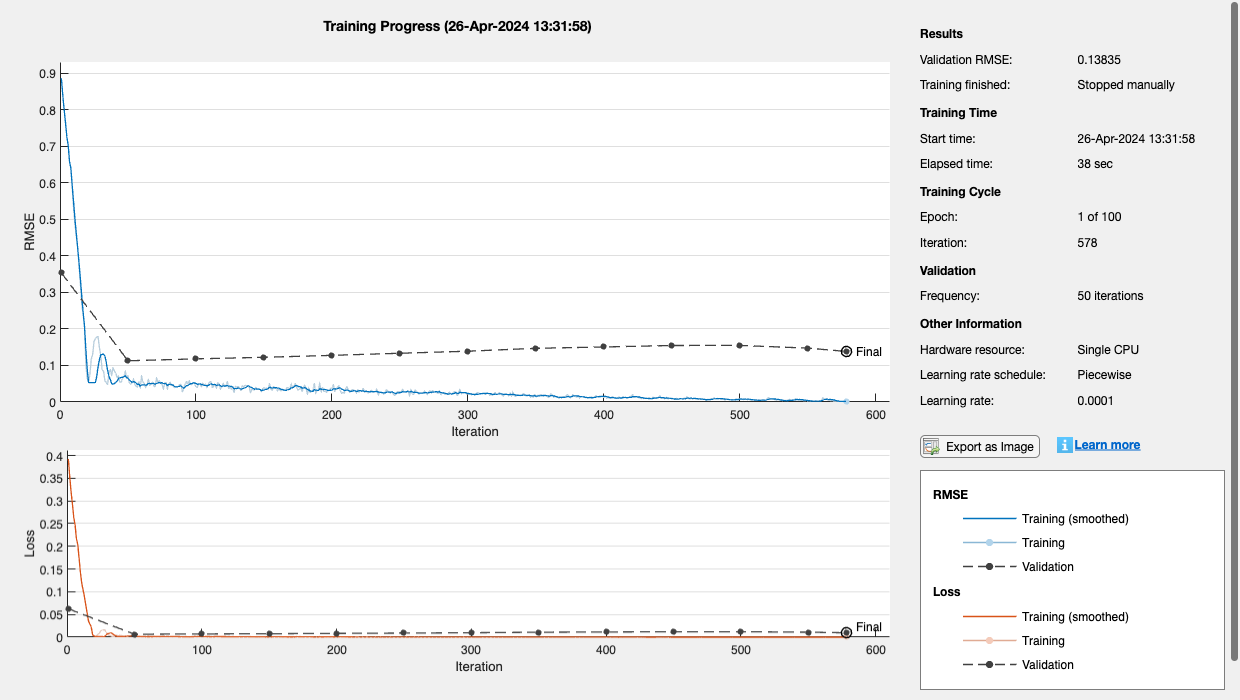

%% configure neural network (NN)
numFeatures     = size(train_data, 1); % Number of features in your data
numHiddenUnits  = 240; % Adjust as needed
numResponses    = 1;

layers = [
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits, 'OutputMode', 'sequence')
    dropoutLayer(0.2)
    tanhLayer
    fullyConnectedLayer(numResponses,'WeightLearnRateFactor',10,'BiasLearnRateFactor',10,'WeightL2Factor',5,'BiasL2Factor',3)
    regressionLayer 
];

% Set training options with the Adam optimizer
options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 2^9, ...
    'SequenceLength', 20, ... % Adjust as needed
    'GradientThreshold', 1, ...
    'InitialLearnRate', 1e-4, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.2, ...
    'LearnRateDropPeriod', 5, ...
    'Shuffle', 'every-epoch', ...  % to reduce biases in training
    'ValidationData', {val_data, val_labels}, ...
    'ValidationFrequency',50,...
    'ExecutionEnvironment', 'auto', ...
    'Plots','training-progress',...
    'Verbose',1);

% Train the LSTM network
net = trainNetwork(train_data, train_labels, layers, options);

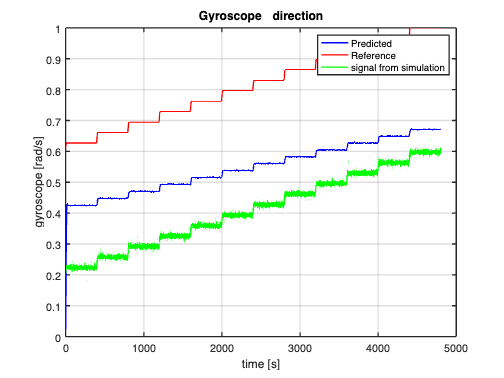


% Test the trained network
predicted_labels = predict(net, test_data);
predicted_labels = predicted_labels';

% plot for gyroscope
aa_g = g_xup(split_idx_train+1:split_idx_val);
aa_g = aa_g';
fig0=figure;
plot(predicted_labels{:},'b');
hold on;
plot(test_labels{:}, 'r');
plot(aa_g,'g');
grid on
xlabel('time [s]');
ylabel('gyroscope [rad/s]');
legend('Predicted','Reference','signal from simulation');
title('Gyroscope _ direction');
exportgraphics(fig0,'Gyroscope _ direction.png','Resolution',300);

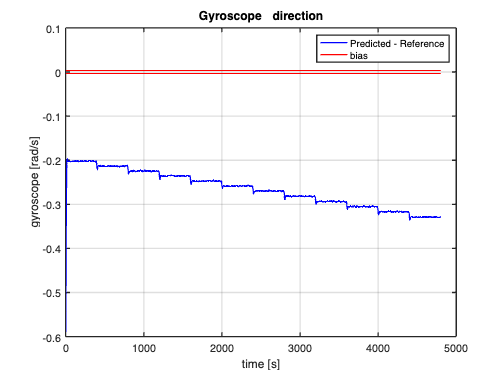


delta_g = predicted_labels{:}-test_labels{:};
bias_gyro = repelem(bias_gyro,length(delta_g));
fig00=figure;
plot(delta_g,'b');
hold on
plot(bias_gyro,'r');
plot(-1*bias_gyro,'r');
grid on
xlabel('time [s]');
ylabel('gyroscope [rad/s]');
legend('Predicted - Reference','bias');
title('Gyroscope _ direction');
exportgraphics(fig00,'Gyroscope Predicted - Reference.png','Resolution',300);

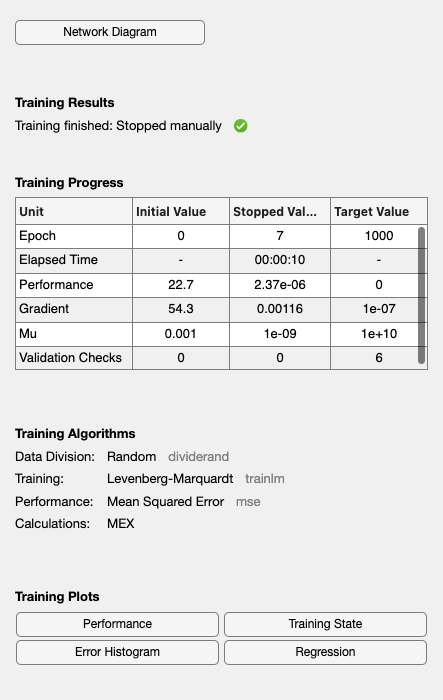

%% Pass the data to FFN
g_lstm                   = num2cell(g_xup');
gyr_ref                  = num2cell(gyr_ref');

% Choose a Training Function
trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation.

% Create a Fitting Network
hiddenLayerSize         = 100;
net                     = feedforwardnet(hiddenLayerSize,trainFcn); % feed forward

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio  = 60/100;
net.divideParam.valRatio    = 20/100;
net.divideParam.testRatio   = 20/100;

% Train the Networks
[netgyr,tr_gyr] = train(net,g_lstm,gyr_ref);


% Test the Networks
gyr_netfit          = netgyr(g_lstm);
e_gyr               = gsubtract(gyr_ref,gyr_netfit);
mse_gyr             = perform(netgyr,gyr_ref,gyr_netfit);

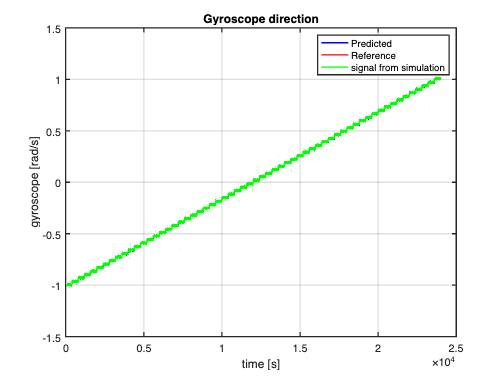

% PLOTS
% plot for gyroscope
aa_g = g_xup;
aa_g = aa_g';
fig1=figure;
plot(cell2mat(gyr_netfit),'b');
hold on;
plot(cell2mat(gyr_ref), 'r');
plot(aa_g,'g');
grid on
xlabel('time [s]');
ylabel('gyroscope [rad/s]');
legend('Predicted','Reference','signal from simulation');
title('Gyroscope direction');
exportgraphics(fig1,'Gyroscope FF direction.png','Resolution',300);

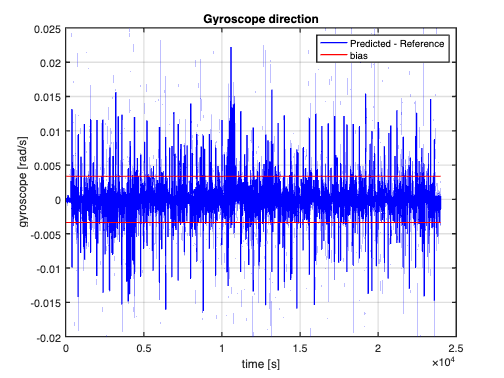


delta_g = cell2mat(gyr_netfit) - cell2mat(gyr_ref);
bias_gyro = simulation.bias_gyro; % Recall bias again from adapted_STEP_GYRORATES.m as is was modified in fig00
bias_gyro = repelem(bias_gyro,length(delta_g));
fig2=figure;
plot(delta_g,'b');
hold on
plot(bias_gyro,'r');
plot(-1*bias_gyro,'r');
grid on
xlabel('time [s]');
ylabel('gyroscope [rad/s]');
legend('Predicted - Reference','bias');
title('Gyroscope direction');
exportgraphics(fig2,'Gyroscope FF direction difference.png','Resolution',300);